clc
data=load('data1.txt')

data =     1.0000    1.5000    3.0000    5.0000   10.0000   20.0000   45.0000   50.0000   30.0000    2.0000    1.0000    0.5000
    3.5000    3.0000    5.0000    9.0000   11.0000   24.0000   49.0000   50.0000   31.0000    4.0000    4.0000    3.5000
    7.0000    6.0000    8.0000    9.0000   15.0000   25.0000   52.0000   55.0000   37.0000    7.0000    5.0000    6.0000


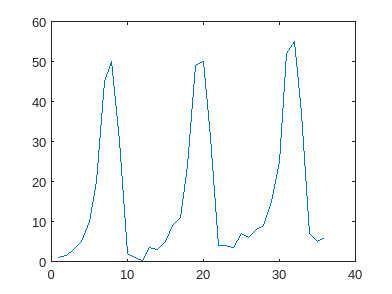

% Create a plot of the data
xt=(data');
yt=xt(:);
plot(yt);

%n number or rows
%m number of columns 
[n,m]=size(data)

n = 3

m = 12

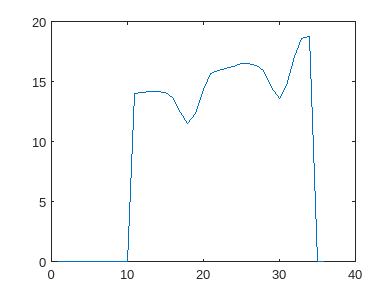

% k pair
% Define the parameters
k = 12;  % value of k
T=length(yt);
% Calculate the rolling mean using the formula
rolling_means=zeros(T,1);
for i=k:T-1
    rolling_means(i-1) = ( (0.5*(yt(i-(k-1)))) + sum(yt(i-(k-2):i-1)) + (0.5*(yt(i))) )/ k;   
end
plot(rolling_means)

%rearange rolling means to match data dimension
MM=reshape(rolling_means,[m,n])'

MM =          0         0         0         0         0         0         0         0         0         0   14.0208   14.0833
   14.1667   14.1667   14.1250   13.7083   12.4583   11.5417   12.3333   14.3750   15.7083   15.9792   16.1250   16.2917
   16.5000   16.5000   16.3750   15.9167   14.5417   13.6250   14.7083   17.0833   18.5833   18.7708         0         0


%differene between observation and rolling means
Stild=data(:,:)-MM(:,:)

Stild =     1.0000    1.5000    3.0000    5.0000   10.0000   20.0000   45.0000   50.0000   30.0000    2.0000  -13.0208  -13.5833
  -10.6667  -11.1667   -9.1250   -4.7083   -1.4583   12.4583   36.6667   35.6250   15.2917  -11.9792  -12.1250  -12.7917
   -9.5000  -10.5000   -8.3750   -6.9167    0.4583   11.3750   37.2917   37.9167   18.4167  -11.7708    5.0000    6.0000


%difference between each columns Stild which is not null in rolling_means
B1=zeros(1,m)

B1 =      0     0     0     0     0     0     0     0     0     0     0     0


for j=1:m
    if j<=m-2
           B1(:,j)=[sum(Stild(2:end,j))]/(n-1);
    else
        B1(:,j)=[sum(Stild(1:end,j))]/(n-1);
    end
end
% moyenne de B
sjprim=mean(B1);
sj= B1-sjprim

sj =   -12.9505  -13.7005  -11.6172   -8.6797   -3.3672    9.0495   34.1120   33.9036   13.9870  -14.7422  -12.9401  -13.0547


sjrep=repmat(sj',n,1)

sjrep =   -12.9505
  -13.7005
  -11.6172
   -8.6797
   -3.3672
    9.0495
   34.1120
   33.9036
   13.9870
  -14.7422


sjj=sjrep(:)

sjj =   -12.9505
  -13.7005
  -11.6172
   -8.6797
   -3.3672
    9.0495
   34.1120
   33.9036
   13.9870
  -14.7422


xijprim=yt-sjrep

xijprim =    13.9505
   15.2005
   14.6172
   13.6797
   13.3672
   10.9505
   10.8880
   16.0964
   16.0130
   16.7422


%ajustement modele
t=1:T;
p1=polyfit(t,xijprim,1); %ajuster un polynoome
% p contient les coefficients en puissance decroissante
yfit = polyval(p1,t)

yfit =    13.0595   13.2625   13.4654   13.6684   13.8713   14.0743   14.2772   14.4802   14.6831   14.8861   15.0890   15.2919   15.4949   15.6978   15.9008   16.1037   16.3067   16.5096   16.7126   16.9155   17.1185   17.3214   17.5244   17.7273   17.9303   18.1332   18.3362   18.5391   18.7421   18.9450   19.1480   19.3509   19.5539   19.7568   19.9598   20.1627


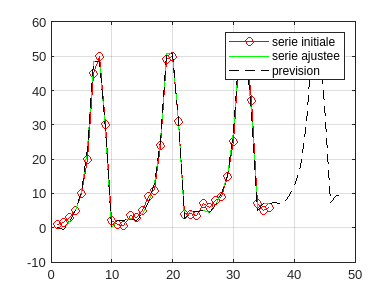

a=p1(:,1);
b=p1(:,2);
ychapeau=yfit'+sjj;
% ychapeau(:,:)= (trim(:,:)-sjrep(:,:));
figure 
plot(yt,'o-r')
grid on
hold on
plot(ychapeau, 'g')
%prevision
tt=T+1:T+12;
yfit2 =(polyval(p1,tt));
ychapeau2 =(yfit2+sj)';
yvao=cat(1,ychapeau,ychapeau2);
plot(yvao,'--k')
legend('serie initiale','serie ajustee','prevision')